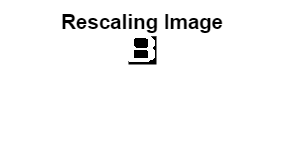


clc; clear; close all; % Clear console, variables, and figures
size = 28; % Define image size
fileID = fopen('input_bram_to_cnn_image.mem', 'rt'); data = textscan(fileID, '%s'); fclose(fileID); % Read file contents
binary_img = strcmp(data{1}, '1'); % Convert '1' to 1 (white), others to 0 (black)
img = reshape(binary_img, size, size)'; % Reshape and transpose to form image matrix
imshow(img, []); title('Rescaling Image'); % Display the image

resized_img = imresize(img, [size, size]); % Resize image (same size in this case)


